params = struct();

% Gravity and air density
params.g   = 9.81;        % m/s^2
params.rho = 1.225;       % kg/m^3   (sea level)

% Geometry 
params.lm = 0.10;   % main body length (m)
params.hm = 0.02;   % main body height (m)
params.wm = 0.06;   % main body width (m)

params.lr = 0.10;   % rod length (m)

params.he = 0.04;   % motor height (m)
params.re = 0.015;  % motor radius (m)

params.rp = 0.025;  % payload radius (m)

% Masses 
m_body    = 0.600;  % kg
m_rod     = 0.025;  % kg per rod
m_motor   = 0.050;  % kg per motor
m_payload = 0.100;  % kg

% Total mass
params.m = m_body + 4*m_rod + 4*m_motor + m_payload;


% Moment of Inertia Calculation
% Approximating components as simple geometric shapes

% Main body (rectangular prism): lm x wm x hm
Ix_body = (1/12) * m_body * (params.hm^2 + params.wm^2);
Iy_body = (1/12) * m_body * (params.lm^2 + params.hm^2);
Iz_body = (1/12) * m_body * (params.lm^2 + params.wm^2);

% Rods (thin rods along x and y axes)
% Assuming rods extend from center to distance lr
% 2 rods along x-axis (±y direction)
Ix_rods_y = 2 * (1/3) * m_rod * params.lr^2;
Iy_rods_y = 2 * m_rod * params.lr^2;  % parallel axis
Iz_rods_y = 2 * m_rod * params.lr^2;  % parallel axis

% 2 rods along y-axis (±x direction)
Ix_rods_x = 2 * m_rod * params.lr^2;  % parallel axis
Iy_rods_x = 2 * (1/3) * m_rod * params.lr^2;
Iz_rods_x = 2 * m_rod * params.lr^2;  % parallel axis

% Motors (cylinders at end of rods)
% Each motor at distance lr from center
Ix_motors = 4 * (0.5 * m_motor * params.re^2 + m_motor * params.lr^2);
Iy_motors = 4 * (0.5 * m_motor * params.re^2 + m_motor * params.lr^2);
Iz_motors = 4 * (0.5 * m_motor * params.re^2 + m_motor * 2 * params.lr^2);

% Payload (sphere at center)
I_payload = (2/5) * m_payload * params.rp^2;

% Total MOI
Ix = Ix_body + Ix_rods_y + Ix_rods_x + Ix_motors + I_payload;
Iy = Iy_body + Iy_rods_y + Iy_rods_x + Iy_motors + I_payload;
Iz = Iz_body + Iz_rods_y + Iz_rods_x + Iz_motors + I_payload;

fprintf('Calculated Moments of Inertia:\n');

Calculated Moments of Inertia:


fprintf('  Ix = %.6f kg·m²\n', Ix);

  Ix = 0.002914 kg·m²


fprintf('  Iy = %.6f kg·m²\n', Iy);

  Iy = 0.003234 kg·m²


fprintf('  Iz = %.6f kg·m²\n', Iz);

  Iz = 0.005728 kg·m²



params.J    = diag([Ix, Iy, Iz]);
params.Jinv = inv(params.J);

% Aerodynamics (cm^2 -> m^2)
params.Ax = 10e-4;   % 10 cm^2
params.Ay = 15e-4;   % 15 cm^2
params.Az = 50e-4;   % 50 cm^2
params.CD = 1.5;

% Max thrust (4 motors, 5 N each)
params.Tmax = 4 * 5;    % N


% State: [x; y; z; u; v; w; phi; theta; psi; p; q; r]
x0 = zeros(12,1);
x0(1:3)   = [0; 0; 0];   % position (m)
x0(4:6)   = [0; 0; 0];   % body velocities (m/s)
x0(7:9)   = [0; 0; 0];   % Euler angles (rad)
x0(10:12) = [0; 0; 0];   % angular rates (rad/s)

% Case 3a
% All orientation angles zero, starting from rest, constant Tmax.

disp('Running Case 3a: Max vertical climb, phi=theta=psi=0');

Running Case 3a: Max vertical climb, phi=theta=psi=0


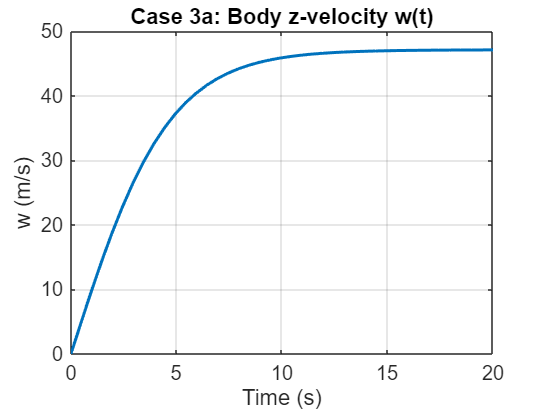


x0_3a = x0;

ctrl_3a = @(t,x) [params.Tmax; 0; 0; 0];  % [T; L; M; N]

tspan_3a = [0 20];   % long enough to approach steady-state velocity

odefun_3a = @(t,x) quad_eom_321(t, x, ctrl_3a, params);
[t3a, X3a] = ode45(odefun_3a, tspan_3a, x0_3a);

u3a = X3a(:,4);
v3a = X3a(:,5);
w3a = X3a(:,6);
V3a = sqrt(u3a.^2 + v3a.^2 + w3a.^2);

figure;
plot(t3a, w3a, 'LineWidth', 1.5); grid on;
xlabel('Time (s)'); ylabel('w (m/s)');
title('Case 3a: Body z-velocity w(t)');

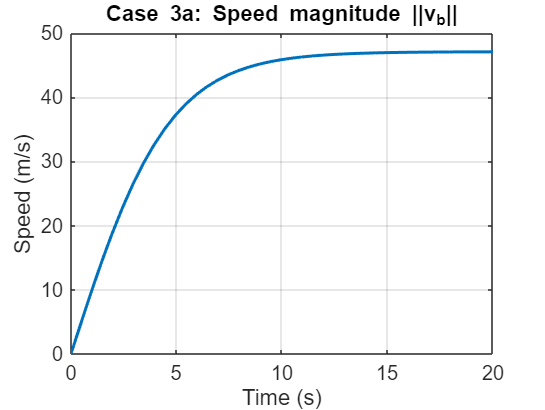


figure;
plot(t3a, V3a, 'LineWidth', 1.5); grid on;
xlabel('Time (s)'); ylabel('Speed (m/s)');
title('Case 3a: Speed magnitude ||v_b||');


%% CASE 3b: Max horizontal velocity
% theta = 26.8910 deg, phi=0, psi=0, starting from rest.

disp('Running Case 3b: Pitch for horizontal speed, theta = 26.8910 deg');

Running Case 3b: Pitch for horizontal speed, theta = 26.8910 deg


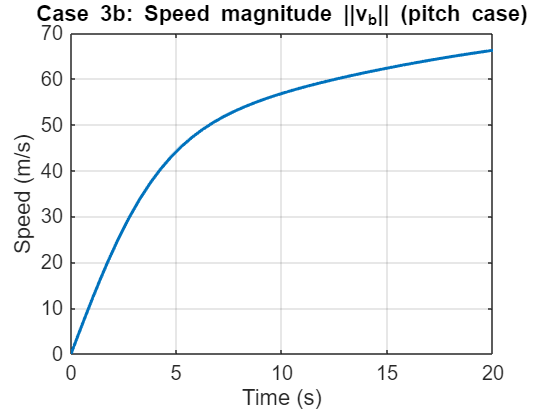


x0_3b = x0;
x0_3b(7) = 0;                       % phi
x0_3b(8) = deg2rad(26.8910);        % theta
x0_3b(9) = 0;                       % psi

ctrl_3b = @(t,x) [params.Tmax; 0; 0; 0];

tspan_3b = [0 20];

odefun_3b = @(t,x) quad_eom_321(t, x, ctrl_3b, params);
[t3b, X3b] = ode45(odefun_3b, tspan_3b, x0_3b);

u3b = X3b(:,4);
v3b = X3b(:,5);
w3b = X3b(:,6);
V3b = sqrt(u3b.^2 + v3b.^2 + w3b.^2);

figure;
plot(t3b, V3b, 'LineWidth', 1.5); grid on;
xlabel('Time (s)'); ylabel('Speed (m/s)');
title('Case 3b: Speed magnitude ||v_b|| (pitch case)');


%%CASE 3c: Max horizontal velocity 
 

phi_deg = 26.8910;   

disp(['Running Case 3c: Roll for horizontal speed, phi = ', ...
      num2str(phi_deg), ' deg']);

Running Case 3c: Roll for horizontal speed, phi = 26.891 deg


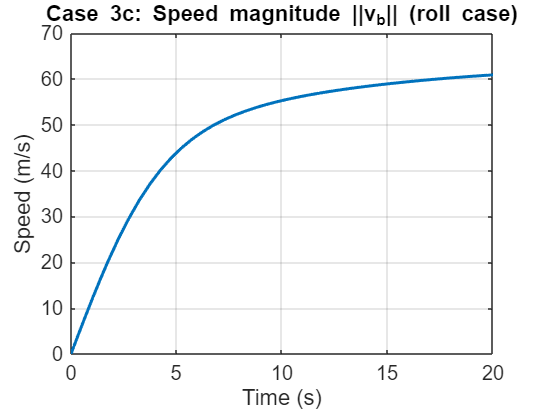


x0_3c = x0;
x0_3c(7) = deg2rad(phi_deg);  % phi
x0_3c(8) = 0;                 % theta
x0_3c(9) = 0;                 % psi

ctrl_3c = @(t,x) [params.Tmax; 0; 0; 0];

tspan_3c = [0 20];

odefun_3c = @(t,x) quad_eom_321(t, x, ctrl_3c, params);
[t3c, X3c] = ode45(odefun_3c, tspan_3c, x0_3c);

u3c = X3c(:,4);
v3c = X3c(:,5);
w3c = X3c(:,6);
V3c = sqrt(u3c.^2 + v3c.^2 + w3c.^2);

figure;
plot(t3c, V3c, 'LineWidth', 1.5); grid on;
xlabel('Time (s)'); ylabel('Speed (m/s)');
title('Case 3c: Speed magnitude ||v_b|| (roll case)');


%% PART 4: Helical trajectory
% Desired inertial trajectory:
%   x_d(t)   = 0.25 cos(2 t)
%   y_d(t)   = 0.25 sin(2 t)
%   z_d(t)   = 0.5 t
%   psi_d(t) = pi/2 + 2 t

disp('Running Part 4: Helical trajectory with trim control');

Running Part 4: Helical trajectory with trim control



tspan_helix = [0 10];

% Compute initial conditions that match trajectory at t=0
% At t=0: x = 0.25*cos(0) = 0.25, y = 0.25*sin(0) = 0, z = 0
x_d0 = [0.25; 0; 0];

% Inertial velocity at t=0
% xdot = -0.5*sin(0) = 0, ydot = 0.5*cos(0) = 0.5, zdot = 0.5
v_I0 = [0; 0.5; 0.5];

% Desired angles at t=0
psi_0 = pi/2;  % 90 degrees

% Desired acceleration at t=0
% xddot = -1.0*cos(0) = -1.0, yddot = -1.0*sin(0) = 0, zddot = 0
xddot_0 = -1.0;
yddot_0 = 0;
zddot_0 = 0;
a_needed_0 = [xddot_0; yddot_0; zddot_0 + params.g];

% Compute phi and theta from acceleration direction
a_mag_0 = norm(a_needed_0);
theta_0 = -asin(a_needed_0(1) / a_mag_0);
phi_0 = atan2(a_needed_0(2), a_needed_0(3));

fprintf('Initial conditions at t=0:\n');

Initial conditions at t=0:


fprintf('  Position: [%.3f, %.3f, %.3f] m\n', x_d0(1), x_d0(2), x_d0(3));

  Position: [0.250, 0.000, 0.000] m


fprintf('  Angles: phi=%.2f deg, theta=%.2f deg, psi=%.2f deg\n', ...
        rad2deg(phi_0), rad2deg(theta_0), rad2deg(psi_0));

  Angles: phi=0.00 deg, theta=5.82 deg, psi=90.00 deg


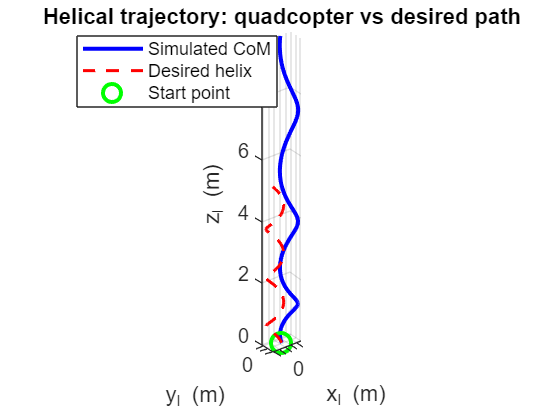


% Rotation matrix at t=0
cphi = cos(phi_0); sphi = sin(phi_0);
ctheta = cos(theta_0); stheta = sin(theta_0);
cpsi = cos(psi_0); spsi = sin(psi_0);

R_ib0 = [ ctheta*cpsi,                    ctheta*spsi,                  -stheta;
          sphi*stheta*cpsi - cphi*spsi,   sphi*stheta*spsi + cphi*cpsi,  sphi*ctheta;
          cphi*stheta*cpsi + sphi*spsi,   cphi*stheta*spsi - sphi*cpsi,  cphi*ctheta ];

R_bi0 = R_ib0.';
v_b0 = R_bi0 * v_I0;

% Angular rates for psi_dot = 2, phi_dot = theta_dot = 0
r_0 = 2 / ctheta;
omega_0 = [0; 0; r_0];

% initial state
x0_helix            = zeros(12,1);
x0_helix(1:3)       = x_d0;          % START AT [0.25; 0; 0]
x0_helix(4:6)       = v_b0;          % initial body velocity
x0_helix(7:9)       = [phi_0; theta_0; psi_0];  % initial angles
x0_helix(10:12)     = omega_0;       % initial angular rates

ctrl_helix = @(t,x) ctrl_helix_trim(t, x, params);

odefun_helix = @(t,x) quad_eom_321(t, x, ctrl_helix, params);
[tH, XH] = ode45(odefun_helix, tspan_helix, x0_helix);

xH = XH(:,1);
yH = XH(:,2);
zH = XH(:,3);

figure;
plot3(xH, yH, zH, 'b-', 'LineWidth', 2); grid on; hold on;

% Reference helix for comparison
tt = linspace(tspan_helix(1), tspan_helix(2), 400);
x_ref = 0.25*cos(2*tt);
y_ref = 0.25*sin(2*tt);
z_ref = 0.5*tt;
plot3(x_ref, y_ref, z_ref, 'r--', 'LineWidth', 1.5);

%  starting points
plot3(x_d0(1), x_d0(2), x_d0(3), 'go', 'MarkerSize', 10, 'LineWidth', 2);

xlabel('x_I (m)');
ylabel('y_I (m)');
zlabel('z_I (m)');
title('Helical trajectory: quadcopter vs desired path');
legend('Simulated CoM', 'Desired helix', 'Start point', 'Location', 'Best');
axis equal;
view(3);

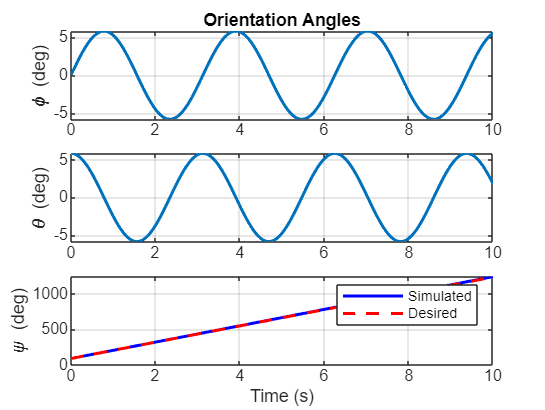


% Plot orientation angles
figure;
subplot(3,1,1);
plot(tH, rad2deg(XH(:,7)), 'LineWidth', 1.5); grid on;
ylabel('\phi (deg)');
title('Orientation Angles');

subplot(3,1,2);
plot(tH, rad2deg(XH(:,8)), 'LineWidth', 1.5); grid on;
ylabel('\theta (deg)');

subplot(3,1,3);
plot(tH, rad2deg(XH(:,9)), 'b-', 'LineWidth', 1.5); grid on;
hold on;
psi_ref = rad2deg(pi/2 + 2*tH);
plot(tH, psi_ref, 'r--', 'LineWidth', 1.5);
ylabel('\psi (deg)');
xlabel('Time (s)');
legend('Simulated', 'Desired');

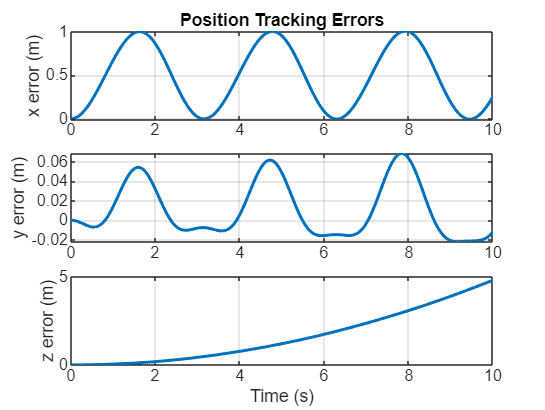


% Plot position errors
figure;
x_ref_t = 0.25*cos(2*tH);
y_ref_t = 0.25*sin(2*tH);
z_ref_t = 0.5*tH;

subplot(3,1,1);
plot(tH, xH - x_ref_t, 'LineWidth', 1.5); grid on;
ylabel('x error (m)');
title('Position Tracking Errors');

subplot(3,1,2);
plot(tH, yH - y_ref_t, 'LineWidth', 1.5); grid on;
ylabel('y error (m)');

subplot(3,1,3);
plot(tH, zH - z_ref_t, 'LineWidth', 1.5); grid on;
ylabel('z error (m)');
xlabel('Time (s)');


disp('Done. Part 4 helical trajectory implemented with trim control.');

Done. Part 4 helical trajectory implemented with trim control.





function xdot = quad_eom_321(t, x, ctrl_fun, params)
% quad_eom_321
%   6-DOF rigid-body equations for a quadcopter with Body 3-2-1 Euler angles.
%
% State x = [ x; y; z;  u; v; w;  phi; theta; psi;  p; q; r ]

% Unpack state
pos   = x(1:3);        %#ok<NASGU>  % inertial position (not used directly)
v_b   = x(4:6);        % [u; v; w] in body frame
phi   = x(7);
theta = x(8);
psi   = x(9);
omega = x(10:12);      % [p; q; r]

u = v_b(1);
v = v_b(2);
w = v_b(3);

% Control inputs
u_ctrl = ctrl_fun(t, x);
T = u_ctrl(1);   % total thrust (N)
L = u_ctrl(2);   % roll moment
M = u_ctrl(3);   % pitch moment
N = u_ctrl(4);   % yaw moment

m    = params.m;
J    = params.J;
Jinv = params.Jinv;

% Rotation matrix R_ib (body -> inertial) for 3-2-1 (psi,theta,phi)
cphi   = cos(phi);   sphi = sin(phi);
ctheta = cos(theta); stheta = sin(theta);
cpsi   = cos(psi);   spsi = sin(psi);

R_ib = [ ctheta*cpsi,                    ctheta*spsi,                  -stheta;
         sphi*stheta*cpsi - cphi*spsi,   sphi*stheta*spsi + cphi*cpsi,  sphi*ctheta;
         cphi*stheta*cpsi + sphi*spsi,   cphi*stheta*spsi - sphi*cpsi,  cphi*ctheta ];

% Forces in body frame 

% Aerodynamic drag
V = sqrt(u^2 + v^2 + w^2);
if V < 1e-8
    F_aero_b = [0; 0; 0];
else
    F_aero_b = -0.5 * params.rho * params.CD * V * ...
               [params.Ax * u;
                params.Ay * v;
                params.Az * w];
end

% Gravity in inertial
F_g_I = [0; 0; -m * params.g];

% Transform gravity to body frame
R_bi = R_ib.';   % inverse rotation
F_g_b = R_bi * F_g_I;

% Thrust in body frame
F_thrust_b = [0; 0; T];

% Total force in body frame
F_total_b = F_thrust_b + F_aero_b + F_g_b;

% Translational dynamics in body frame
v_dot_b = (1/m) * F_total_b - cross(omega, v_b);

% Rotational dynamics
tau       = [L; M; N];
omega_dot = Jinv * (tau - cross(omega, J*omega));

% Euler angle kinematics (3-2-1)
T_eul = [1,  sin(phi)*tan(theta),  cos(phi)*tan(theta);
         0,  cos(phi),            -sin(phi);
         0,  sin(phi)/cos(theta),  cos(phi)/cos(theta)];

eul_dot = T_eul * omega;

% Inertial position kinematics
pos_dot = R_ib * v_b;

% Pack derivative
xdot = [pos_dot;
        v_dot_b;
        eul_dot;
        omega_dot];
end

% --------------------------------------------------------------------- %

function u_ctrl = ctrl_helix_trim(t, x, params)
% ctrl_helix_trim
%   Trim control for the helical trajectory.
%
% For trim state:
%   - Linear acceleration matches desired trajectory
%   - Angular acceleration is zero
%   - Thrust provides the needed acceleration

m = params.m;
g = params.g;

% Desired inertial acceleration
xddot = -1.0 * cos(2*t);
yddot = -1.0 * sin(2*t);
zddot =  0.0;

% Total acceleration needed (gravity compensated)
a_needed = [xddot; yddot; zddot + g];

% Thrust magnitude
T = m * norm(a_needed);

% For trim, angular velocities should match desired rates
% psi_dot = 2, phi_dot = 0, theta_dot = 0
psi_dot_d = 2;

% Get desired angles
psi_d = pi/2 + 2*t;
theta_d = -asin(a_needed(1) / norm(a_needed));
phi_d = atan2(a_needed(2), a_needed(3));

% Transform angular velocity from Euler rates to body rates
% omega = T_eul^(-1) * eul_dot
cphi = cos(phi_d);
sphi = sin(phi_d);
ctheta = cos(theta_d);
stheta = sin(theta_d);

% For trim with constant phi and theta (phi_dot = theta_dot = 0)
% and psi_dot = 2:
% [p; q; r] = T_eul^(-1) * [0; 0; psi_dot]
r_d = psi_dot_d / ctheta;
p_d = 0;
q_d = 0;

% For zero angular acceleration in trim:
% tau = omega x (J * omega)
J = params.J;
omega_d = [p_d; q_d; r_d];
tau_trim = cross(omega_d, J * omega_d);

L = tau_trim(1);
M = tau_trim(2);
N = tau_trim(3);

u_ctrl = [T; L; M; N];
end